## Ejemplos de soluciones de las Ecuaciones de Bloch

Las ecuaciones de Bloch son:

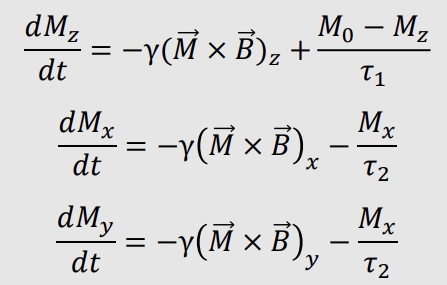

La excitación que nos interesa es la de un campo longitudinal z constante y un campo transversal x e y con polarización circular.

#### Ecuaciones de Landau-Lipshitz

El primer caso sería el caso en el que los tiempos de relajación tienden a infinito, de forma que en la práctica nos quedamos con las ecuaciones de Landau-Lipshitz. Hay que tener cuidado por que si no hay relajación, las soluciones particulares no desaparecen, se decir, nunca se llega a un estado estacionario. Para el primer caso da igual, por que la única solución es la estacionaria, para cualquier estado inicial. 


$$\begin{array}{l}
\tau_1 =\tau_2 =\infty \\
B_0 =30\\
B_1 =0
\end{array}$$


Tenemos una precesión, como en la transparencia 5.

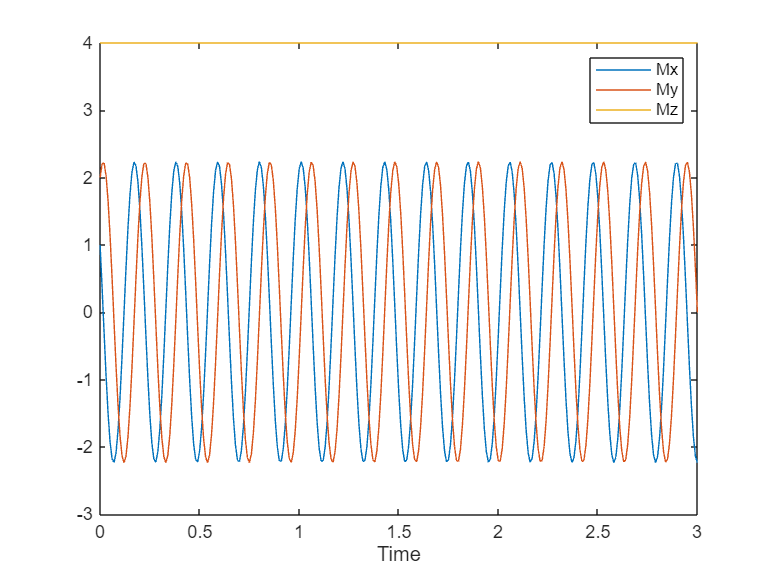

beB0 = BlochEqSolver(inf, inf, 30, 0, 1, 1, 30, 0.01, [1 2 4]);
% Se puede variar el vector de condiciones iniciales   ^ ^ ^, siempre da la
% misma solución que precesiona
beB0.plot(3);

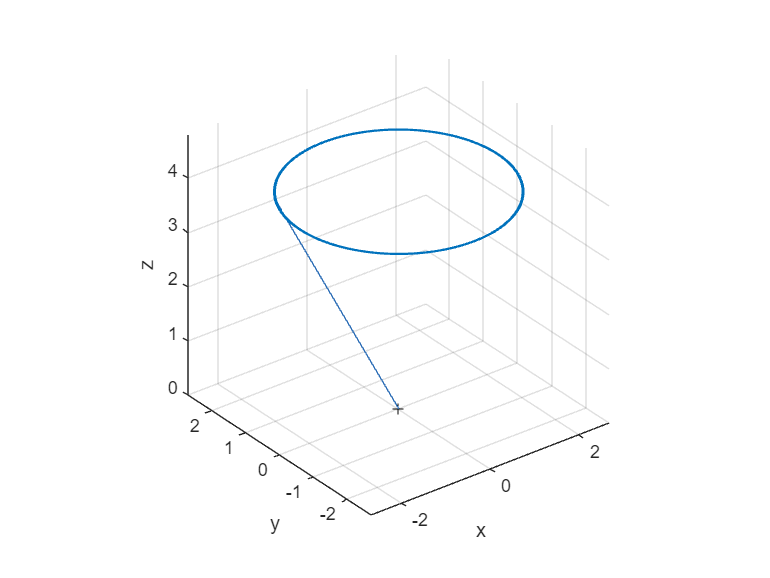

beB0.plot3;

Si comparamos, la precesión tiene una componente de frecuencia que corresponde solo con la frecuencia de Larmor.

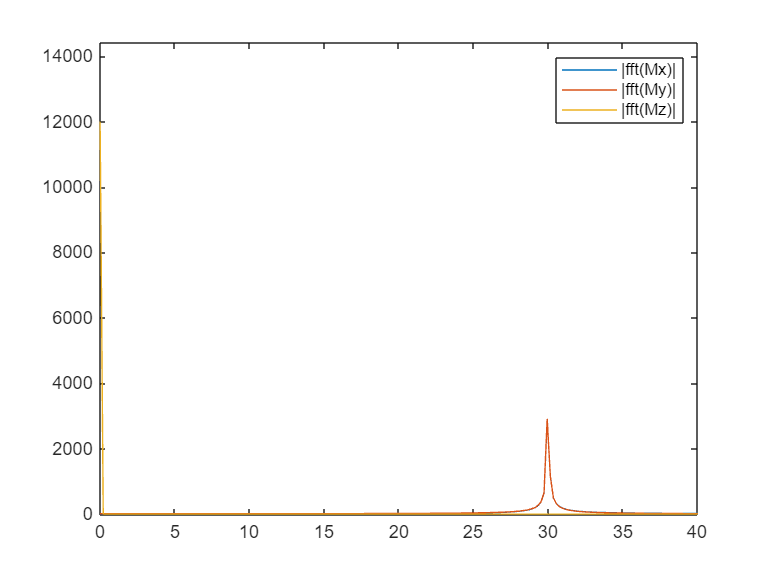

beB0.fft(40);

Si la excitación pasa a ser una polarización circular:


$$\begin{array}{l}
\tau_1 =\tau_2 =\infty \\
B_0 =0\\
B_1 =8\\
\omega =5
\end{array}$$


La respuesta ya no es una precesión a la fercuencia de Larmor, sino una oscilación impredecible.

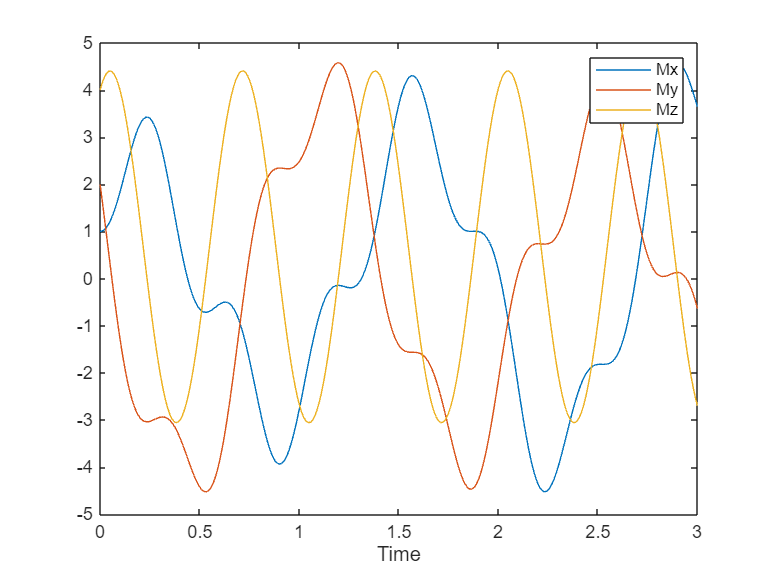

beB1 = BlochEqSolver(inf, inf, 0, 8, 5, 1, 30, 0.01, [1 2 4]);
beB1.plot(3);

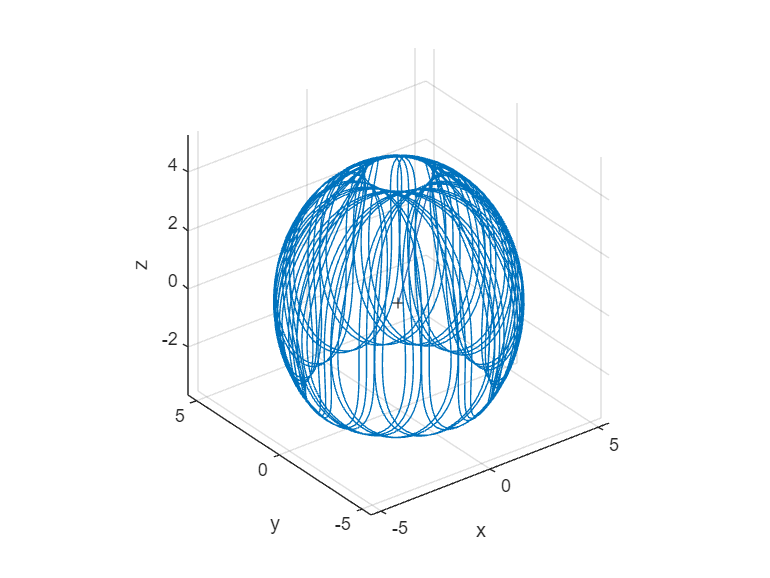

beB1.plot3;

Ahora ponemos los dos a la vez, campo longitudinal constante y transversal con polarización circular:


$$\begin{array}{l}
\tau_1 =\tau_2 \longrightarrow \infty \\
B_0 =10\\
B_1 =8\\
\omega =5
\end{array}$$


(Uso tiempos de relajación largos pero no infinitos, para que la oscilación inicial acabe desapareciendo)

Vemos que la frecuencia de Larmor aparece, aunque distorsionada, correspondiente a la oscilación inicial, y aparece principalmente la frecuencia de la excitación.

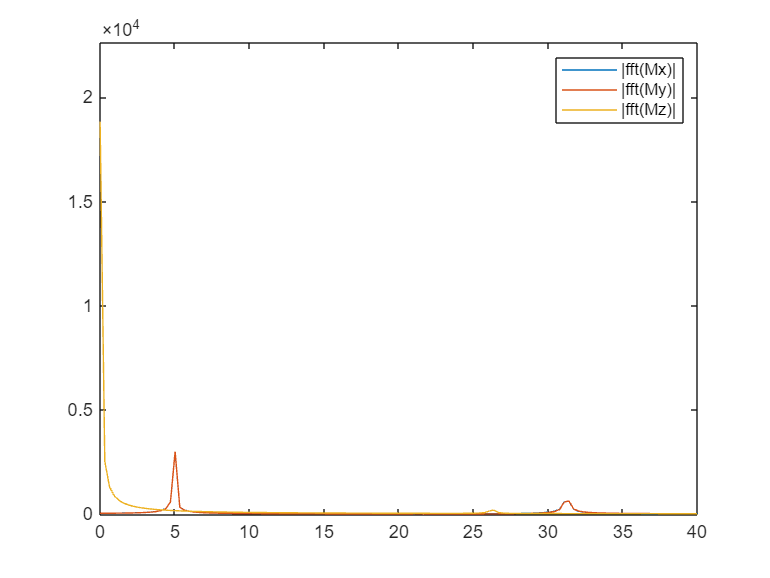

beB01 = BlochEqSolver(10, 10, 30, 8, 5, 1, 20, 0.01, [1 2 4]);
beB01.fft(40);

Vemos como después de las oscilaciones iniciales, acaba estabilizandose en la oscilaciópn forzada que esperamos.

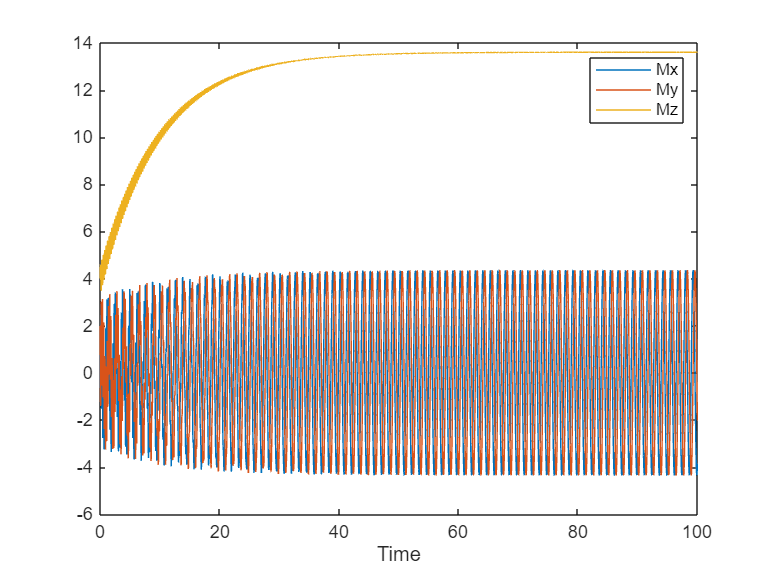

beB01 = BlochEqSolver(10, 10, 30, 8, 5, 1, 100, 0.01, [1 2 4]);
beB01.plot;

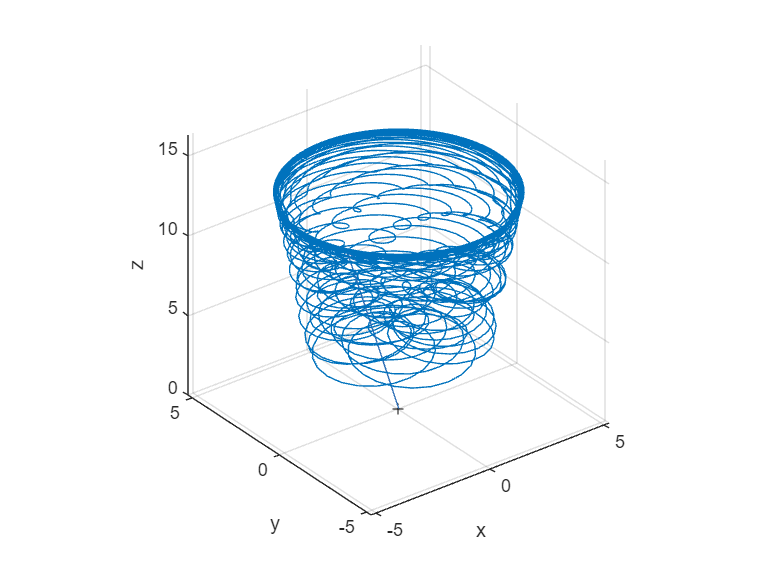

beB01.plot3;

#### Tiempos de relajación

Si quitamos la excitación (el campo magnético) el sistema se convierte en un sistema con tiempo de relajación, la magnetización en dirección z se relaja según según su constante $\tau_1$ y la magnetización en las direcciones x e y según su constante $\tau_2$.

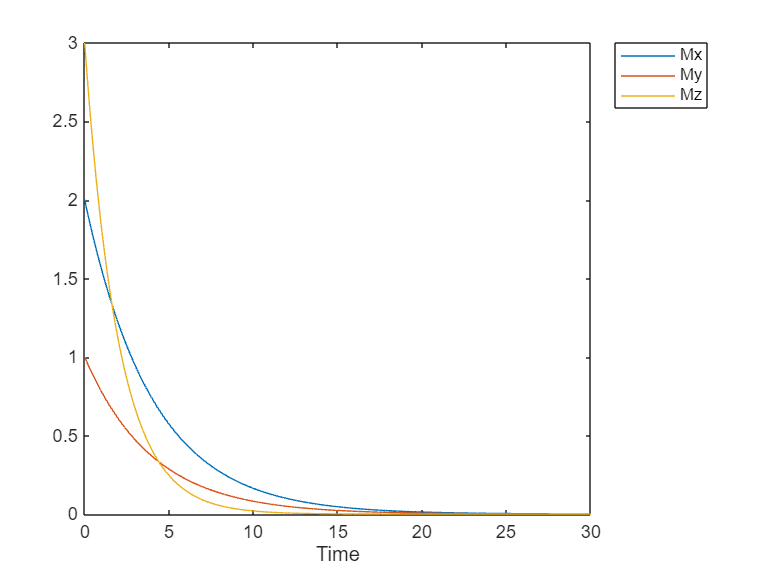

betau = BlochEqSolver(2, 4, 0, 0, 5, 1, 30, 0.01, [2 1 3]);
betau.plot;

Si ponemos un campo magnético constante en dirección z, ahora la magnetización en dirección z se relaja hacia el valor que le corresponde, en este caso 5. Las magnetizaciones tranversales interaccionan a través del termino de producto vectorial pero eventualmente también desaparecen.

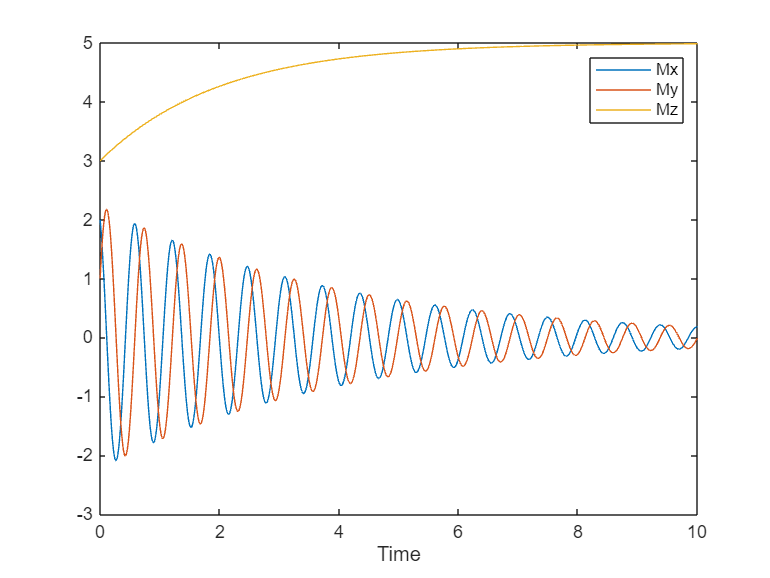

betau = BlochEqSolver(2, 4, 10, 0, 5, 1, 30, 0.01, [2 1 3]);
% Se puede variar el vector de condiciones iniciales   ^ ^ ^, siempre da la
% misma solución que oscila hasta la posición estable
betau.plot(10);

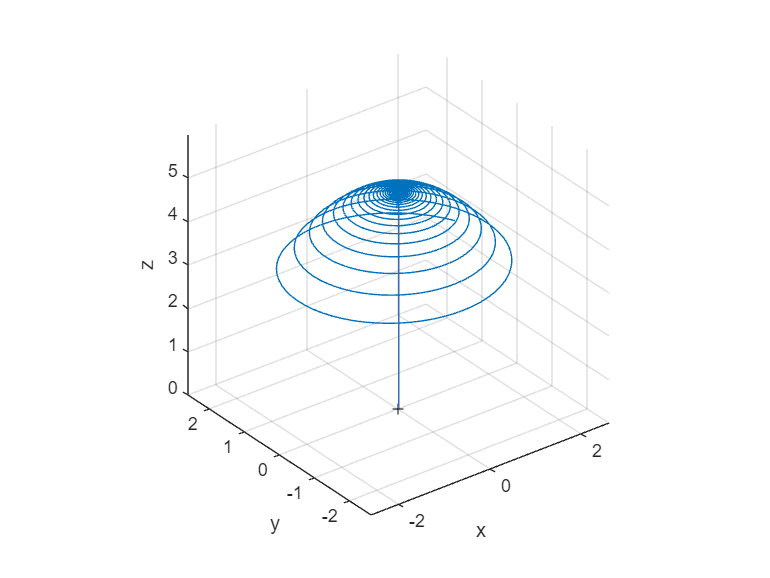

betau.plot3;

Si además añadimos la excitación transversal, la magnetización no llega a un valor constante, sino que acaba con una respuesta estacionaria a la frecuencia de la escitación.

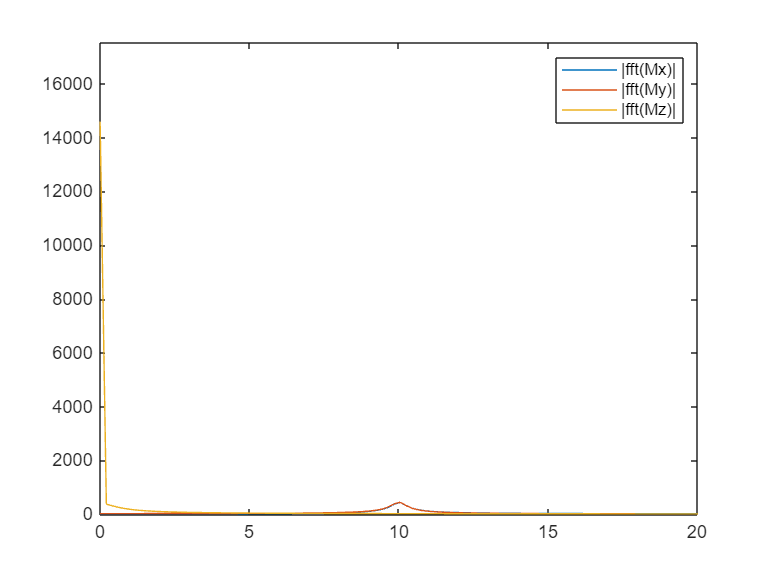

betau = BlochEqSolver(2, 4, 10, 8, 5, 1, 30, 0.01, [2 1 3]);

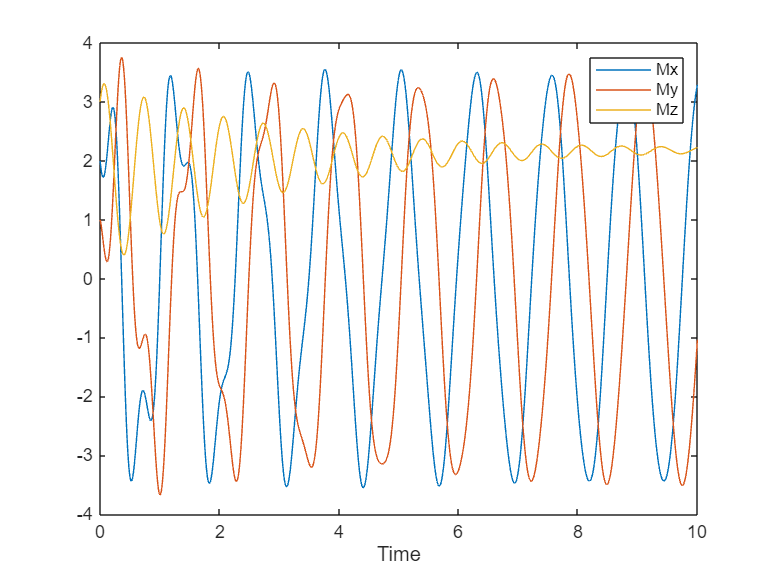

betau.plot(10);

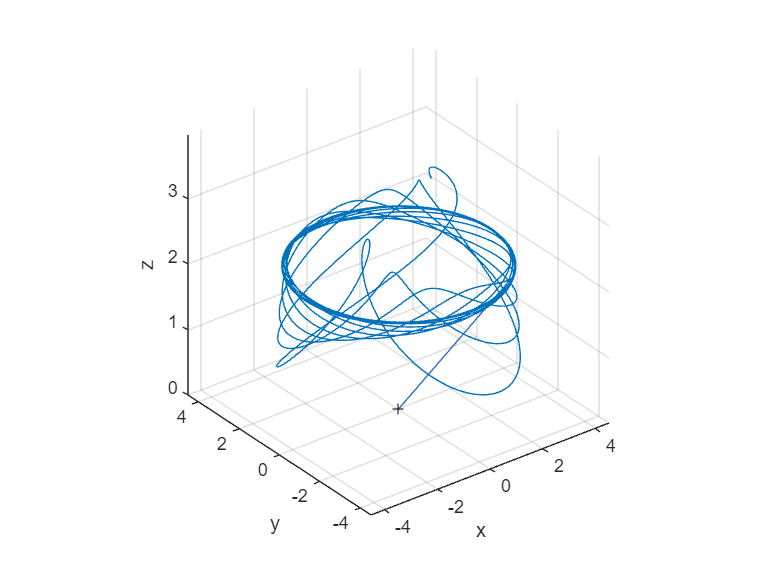

betau.plot3;

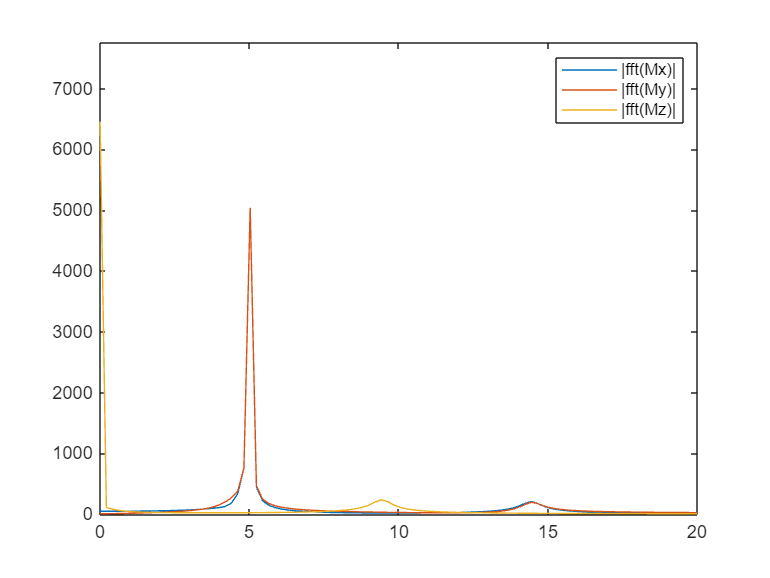

betau.fft(20);

#### Retraso entre el campo magnético y la magnetización

Si los tiempos de relajación son muy largos, (pocas pérdidas) nos encontramos en las ecuaciones de Landau-Lipshitz que predicen que el campo magnético y la magnetización acaban estando en fase.

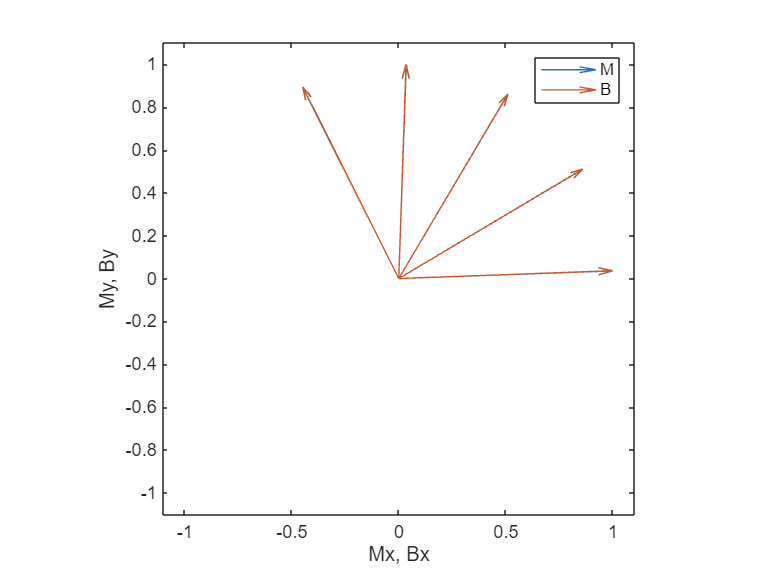

bedelay = BlochEqSolver(100, 200, 10, 8, 5, 1, 3000, 0.1, [2 1 4]);
bedelay.plotd(5,1);

Para tiempos de relajación menores (mayores pérdidas) aparece un desfase que aumenta cuando disminuyen los tiempos de relajación.


$$\tau_1 ,\tau_2 \searrow \;\Longrightarrow \;\phi \nearrow$$


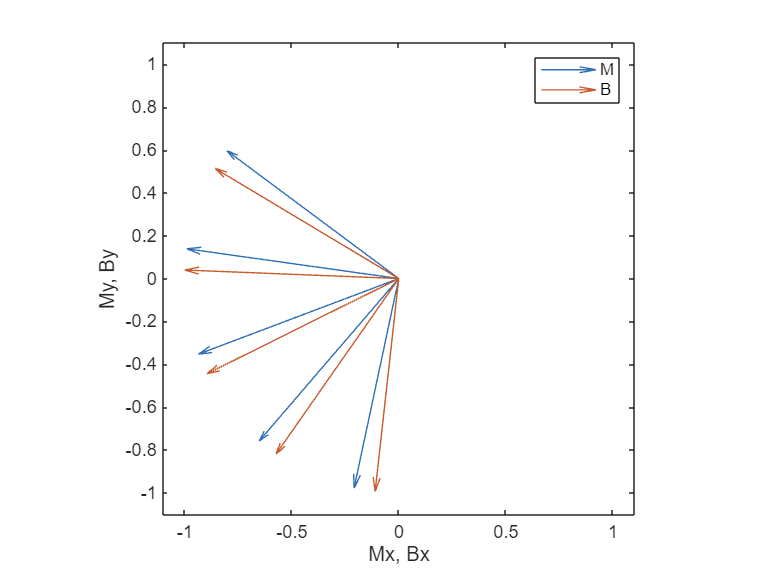

bedelay = BlochEqSolver(1, 2, 10, 8, 5, 1, 300, 0.1, [2 1 4]);
bedelay.plotd(5, 1);

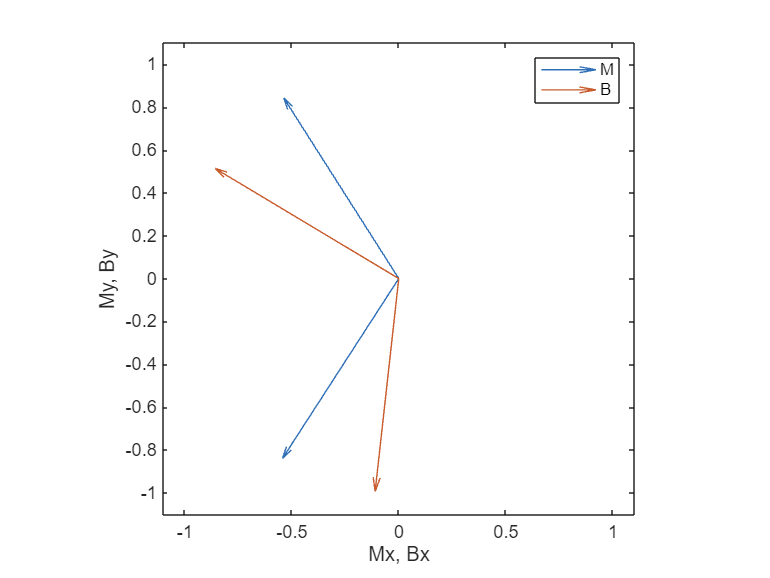

bedelay = BlochEqSolver(.2, .4, 10, 8, 5, 1, 300, 0.1, [2 1 4]);
bedelay.plotd(2, 4);

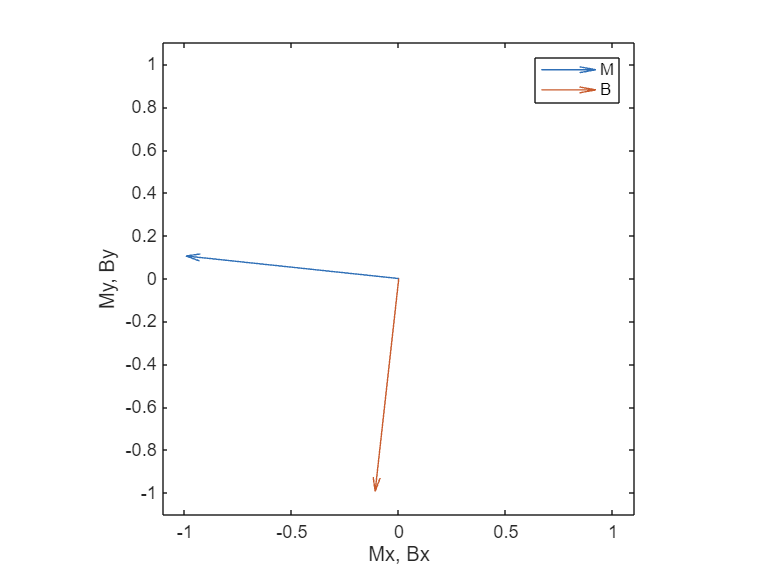

bedelay = BlochEqSolver(.001, .001, 10, 8, 5, 1, 300, 0.1, [2 1 4]);
bedelay.plotd;